# LABORATORIO 4 - CINEMÁTICA DIRECTA

## MÓDELO CINEMÁTICO DIRECTO - PHANTOM X

sym pi;
syms beta;
syms q_1 q_2 q_3 q_4;
syms l_1 l_2 l_3 l_4;
DHparameters = [[q_1 l_1 0 pi/2 0];
           [-q_2 0 l_2 0 beta];
           [q_3 0 l_3 0 -beta];
           [-q_4 0 0 pi/2 pi/2];
           [0 l_4 0 0 0]];
T01 = MTH(DHparameters(1,:))

$$T01 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & 0 & \sin\left(q_{1}\right) & 0\\ \sin\left(q_{1}\right) & 0 & -\cos\left(q_{1}\right) & 0\\ 0 & 1 & 0 & l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T12 = MTH(DHparameters(2,:))

$$T12 = \left(\begin{array}{cccc} \cos\left(\beta -q_{2}\right) & -\sin\left(\beta -q_{2}\right) & 0 & l_{2}\,\cos\left(\beta -q_{2}\right)\\ \sin\left(\beta -q_{2}\right) & \cos\left(\beta -q_{2}\right) & 0 & l_{2}\,\sin\left(\beta -q_{2}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T23 = MTH(DHparameters(3,:))

$$T23 = \left(\begin{array}{cccc} \cos\left(\beta -q_{3}\right) & \sin\left(\beta -q_{3}\right) & 0 & l_{3}\,\cos\left(\beta -q_{3}\right)\\ -\sin\left(\beta -q_{3}\right) & \cos\left(\beta -q_{3}\right) & 0 & -l_{3}\,\sin\left(\beta -q_{3}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T34 = MTH(DHparameters(4,:))

$$T34 = \left(\begin{array}{cccc} \cos\left(q_{4}-\frac{\pi }{2}\right) & 0 & -\sin\left(q_{4}-\frac{\pi }{2}\right) & 0\\ -\sin\left(q_{4}-\frac{\pi }{2}\right) & 0 & -\cos\left(q_{4}-\frac{\pi }{2}\right) & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T45 = MTH(DHparameters(5,:))

$$T45 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & l_{4}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matriz de transformación homogénea del efector final, siendo el punto de referencia la base (0), es decir T05

T05 = T01*T12*T23*T34*T45

### Gráfica del modelo con el Toolbox de PeterCorke:

q =      0     0     0     0


 
phantomX = 
 
noname:: 4 axis, RRRR, stdDH, slowRNE                            
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|        9.7|          0|     1.5708|          0|
|  2|         q2|          0|      10.67|          0|    1.24159|
|  3|         q3|          0|     10.135|          0|   -1.24159|
|  4|         q4|          0|          0|     1.5708|     1.5708|
+---+-----------+-----------+-----------+-----------+-----------+
tool:    t = (0, 0, 11.2), RPY/xyz = (0, 0, 0) deg               
 


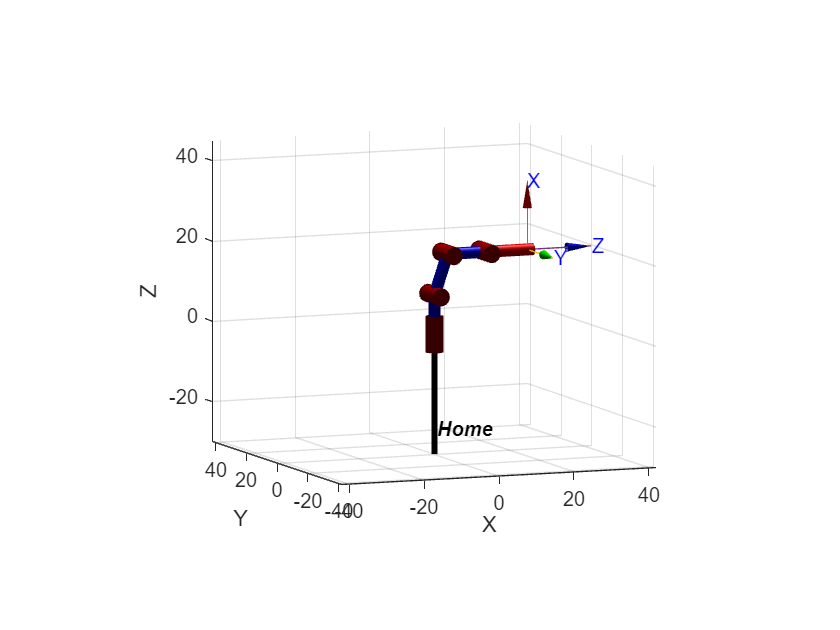

q =     0.4363    0.4363    0.3491   -0.3491


 
phantomX = 
 
noname:: 4 axis, RRRR, stdDH, slowRNE                            
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|        9.7|          0|     1.5708|          0|
|  2|         q2|          0|      10.67|          0|    1.24159|
|  3|         q3|          0|     10.135|          0|   -1.24159|
|  4|         q4|          0|          0|     1.5708|     1.5708|
+---+-----------+-----------+-----------+-----------+-----------+
tool:    t = (0, 0, 11.2), RPY/xyz = (0, 0, 0) deg               
 


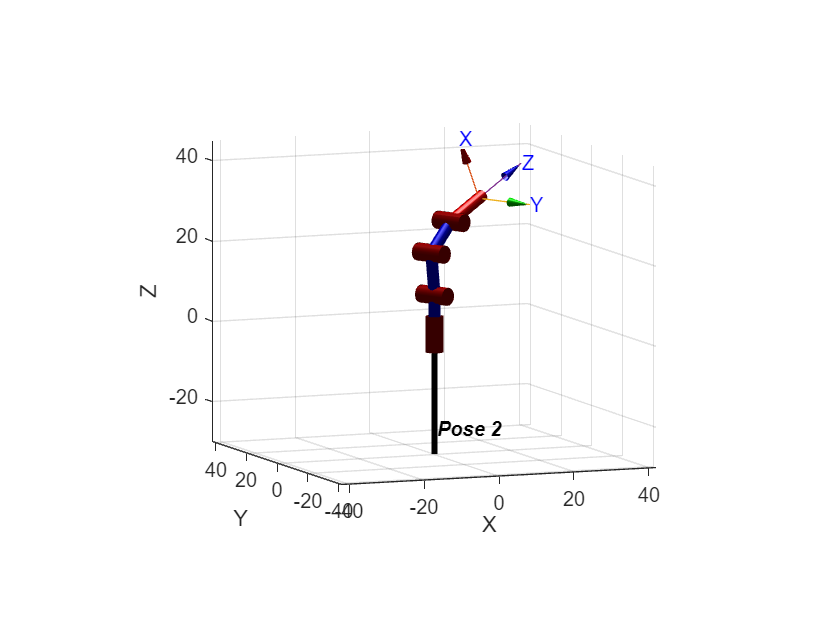

q =    -0.6109    0.6109   -0.5236    0.5236


 
phantomX = 
 
noname:: 4 axis, RRRR, stdDH, slowRNE                            
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|        9.7|          0|     1.5708|          0|
|  2|         q2|          0|      10.67|          0|    1.24159|
|  3|         q3|          0|     10.135|          0|   -1.24159|
|  4|         q4|          0|          0|     1.5708|     1.5708|
+---+-----------+-----------+-----------+-----------+-----------+
tool:    t = (0, 0, 11.2), RPY/xyz = (0, 0, 0) deg               
 


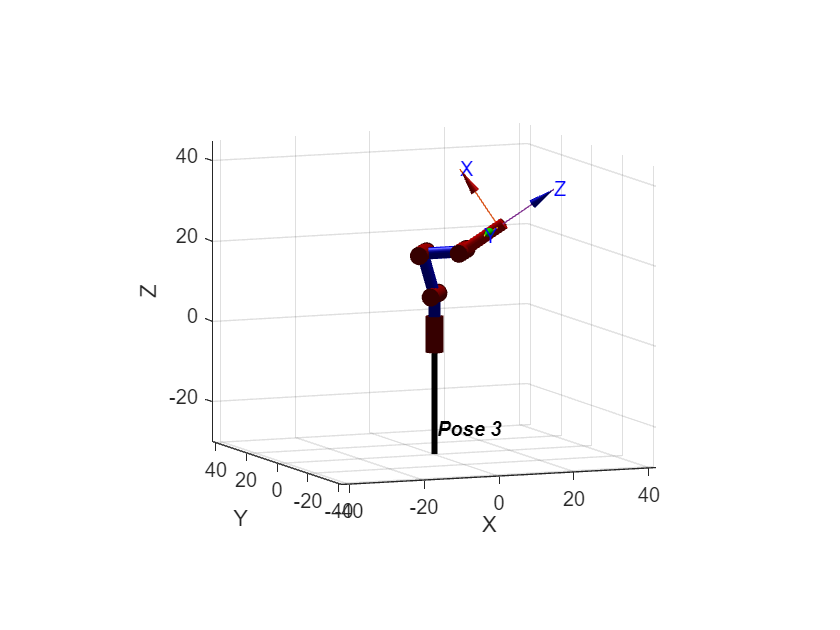

q =     1.4835   -0.3491    0.9599    0.4363


 
phantomX = 
 
noname:: 4 axis, RRRR, stdDH, slowRNE                            
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|        9.7|          0|     1.5708|          0|
|  2|         q2|          0|      10.67|          0|    1.24159|
|  3|         q3|          0|     10.135|          0|   -1.24159|
|  4|         q4|          0|          0|     1.5708|     1.5708|
+---+-----------+-----------+-----------+-----------+-----------+
tool:    t = (0, 0, 11.2), RPY/xyz = (0, 0, 0) deg               
 


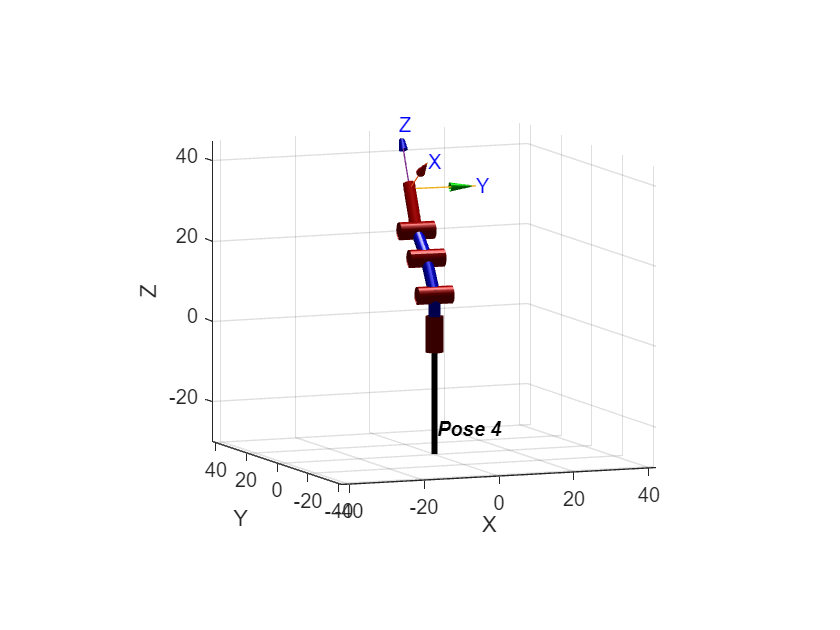

q =          0   -0.1745    1.5708    1.5708


 
phantomX = 
 
noname:: 4 axis, RRRR, stdDH, slowRNE                            
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|        9.7|          0|     1.5708|          0|
|  2|         q2|          0|      10.67|          0|    1.24159|
|  3|         q3|          0|     10.135|          0|   -1.24159|
|  4|         q4|          0|          0|     1.5708|     1.5708|
+---+-----------+-----------+-----------+-----------+-----------+
tool:    t = (0, 0, 11.2), RPY/xyz = (0, 0, 0) deg               
 


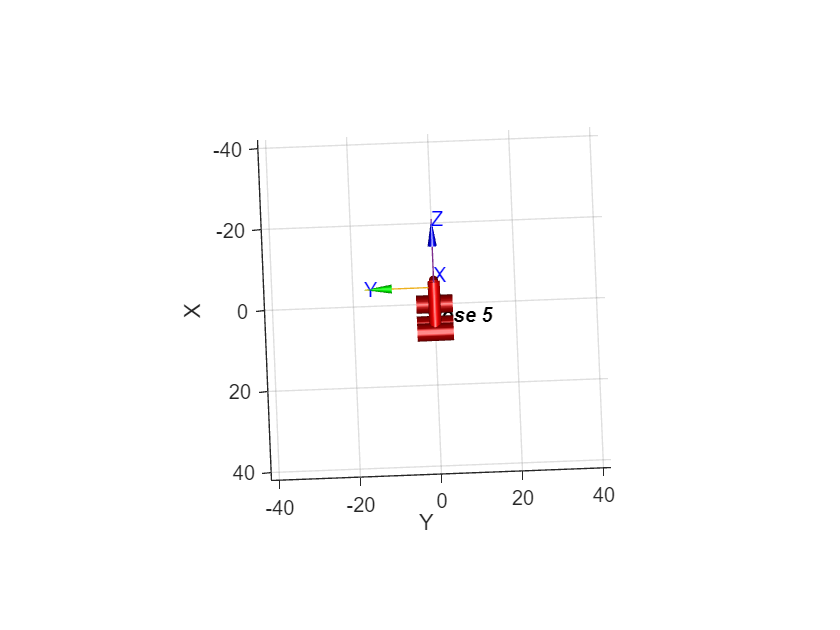

%Eliminar simbolos
clear pi beta;
%Poses
q1 = [0, 0, 0, 0];
q2 = [25, 25, 20, -20];
q3 = [-35, 35, -30, 30];
q4 = [85, -20, 55, 25];
q5 = [0, -10, 90, 90];
poses = [q1; q2; q3; q4; q5];

names = ["Home", "Pose 2", "Pose 3", "Pose 4", "Pose 5"];
beta = deg2rad(71.138);
DHparameters = [[0 9.7 0 pi/2 0 0];
                [0 0 10.67 0 0 beta];
                [0 0 10.135 0 0 -beta];
                [0 0 0 pi/2 0 pi/2];
                [0 11.19 0 0 0 0]];
%Generar las ilustraciones
for i = 1:length(poses)
    q = poses(i, :)*pi/180
    L(1) = Link(DHparameters(1,:));
    L(2) = Link(DHparameters(2,:));
    L(3) = Link(DHparameters(3,:));
    L(4) = Link(DHparameters(4,:));
    phantomX = SerialLink(L);
    phantomX.tool = trotx(0) * transl(0, 0, 11.19)
    phantomX.name = names(i);
    figure()
    phantomX.plot(q);
    view([-22.3 7.9])
    zlim([-30 45])
end

%Funciones
function [H] = MTH(rowDH)
    theta = rowDH(1);
    d = rowDH(2);
    a = rowDH(3);
    alpha = rowDH(4);
    offset = rowDH(5);
    H = trotz(theta + offset)*transl(0,0,d)*transl(a,0,0)*trotx(alpha);
end